data = readtable("confusion_mat.txt")

data = 256×7 table
    T     TP      FP     FN    TN    TPR    FPR
    __    ___    ____    __    __    ___    ___

     0    151    1111    0     0      1      1 
     1    151    1111    0     0      1      1 
     2    151    1111    0     0      1      1 
     3    151    1111    0     0      1      1 
     4    151    1111    0     0      1      1 
     5    151    1111    0     0      1      1 
     6    151    1111    0     0      1      1 
     7    151    1111    0     0      1      1 
     8    151    1111    0     0      1      1 
     9    151    1111    0     0      1      1 
    10    151    1111    0     0      1      1 
    11    151    1111    0     0      1      1 
    12    151    1111    0     0      1      1 
    13    151    1111 

TPR = round(data.TPR,2)

TPR =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


FPR = round(data.FPR,2)

FPR =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


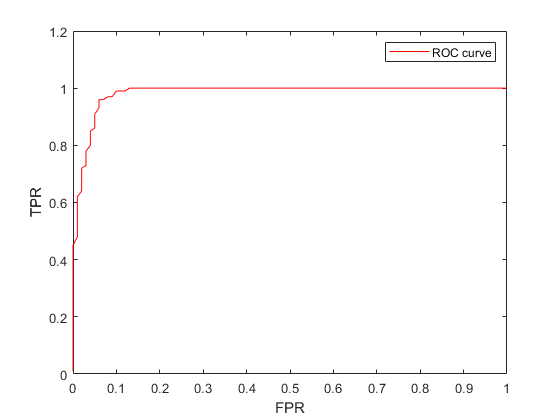

plot(FPR,TPR,"r-")
xlim([0 1])
ylim([0 1.2])
xlabel("FPR")
ylabel("TPR")
legend("ROC curve")

A = data.T(data.TPR >= 0.96)

A =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


B = data.T(data.FPR <= 0.06)

B =    207
   208
   209
   210
   211
   212
   213
   214
   215
   216
